# Demo: Green's Functions in 2D Acoustics Using CGLS with Interesting Multipoles

We will forgo the theory for Greens Functions here given that it can be found in demo_Green2D.mlx.

This file expands on previous Greens Demos by utilizing a more complicated source function. We will now have the following:


$$f_0\left(\textbf{x},t\right) = w_0(t)*\delta\left(\textbf{x}-\textbf{x}_\ast\right)\\\ \ \ \ \ \ + w_1(t)*\frac{\partial}{\partial \textbf{x}_1}*\delta\left(\textbf{x}-\textbf{x}_\ast\right)\\\ \ \ \ \ \ + w_2(t)*\frac{\partial}{\partial \textbf{x}_2}*\delta\left(\textbf{x}-\textbf{x}_\ast\right)$$


## Initial set up

clear

t_final = 1;
domain_t = [0,t_final];
domain_x = [0,1];
domain_y = [0,1.2];


% Initial conditions
p0 = @(x,y) zeros(size(x));
vx0 = @(x,y) zeros(size(x));
vy0 = @(x,y) zeros(size(x));

% Initializing PML
pml = PML2D(WidthLeft=0.2,WidthRight=0.2,WidthBottom=0.2,WidthTop=0.2);

% Single point receiver
x_rcv = 0.2;
y_rcv = 0.5;
grid_x_pt = Grid1D(domain_x,x_rcv);
grid_y_pt = Grid1D(domain_y,y_rcv);
gridSp_rcv = GridSpace2D(grid_x_pt,grid_y_pt);

% Continuous acoustic medium object function
% medium = AcousticMedium1D.layered( ...
%     BetaValues=[0.25,0.5,1], ...
%     KappaValues=[4,3,6], ...
%     Domain=domain_x, ...
%     RelativeWidths=[0.5,0.3,0.2]);
medium = AcousticMedium2D.constant(BetaValue=1,KappaValue=1);

## Computing pressure data directly

The time interval over which pressure data is computed is $[0,T]$.

As usual, we discretize the time domain by introducing a uniform grid with grid size $\Delta_t$ in such a way the required CFL condition is satisfied. We refer to the resulting time grid as the ***computational time grid***.

% Spatial computational grids and grid spaces
Nx=201;
Ny=211;
grid_x_primal = Grid1DUnifPrimal(domain_x,Nx);
grid_y_primal = Grid1DUnifPrimal(domain_y,Ny);
grid_x_dual   = Grid1DUnifDual(grid_x_primal);
grid_y_dual   = Grid1DUnifDual(grid_y_primal);

gridSp_P = GridSpace2D(grid_x_primal, grid_y_primal);   %grid space for pressure
gridSp_Vx = GridSpace2D(grid_x_dual,  grid_y_primal);   %grid spaces for velocity in x
gridSp_Vy = GridSpace2D(grid_x_primal,  grid_y_dual);   %grid spaces for velocity in y

h = gridSp_P.h; %spatial grid sizes, h = [dx,dy]

% Sampling medium parameters to compute max wave speed 
[~,~,~,wspeed,cMax] = sampleMedium2D(gridSp_P,medium);

% Determining computational time grid size
CFL_factor = 0.8;
dt_cmp = CFL_factor*(6/7)/(cMax*sqrt(sum(1./h.^2))); %CFL condition for 2-4 FDM
Nt_cmp = ceil(diff(domain_t)/dt_cmp)+1;
dt_cmp = diff(domain_t)/(Nt_cmp-1); %recomputing to ensure time domain divisible by dt

% Computational time points
t_cmp = domain_t(1):dt_cmp:domain_t(2);

In practice, the pressure data is sampled/stored on a uniform time grid that is much coarser than the computational grid. This results in a time series vector for the pressure data, $\mathbf d\in\mathbb R^{K}$, with $d_i \approx p(x_r,y_r,t_i)$ for $i=0,1,...,K-1$ where $K$ is the total number of time points for the receiver. This new time grid is referred to as the ***receiver time grid***.

% Receiver time points
Nt_rcv = 101;
t_rcv  = linspace(domain_t(1),domain_t(2),Nt_rcv);
dt_rcv = diff(domain_t)/(Nt_rcv-1);

Here we initialize the monopole source for the 2D acoustic problem, $f(x,y,t) = w(t) \delta(x-x_c,y-y_c)
$.

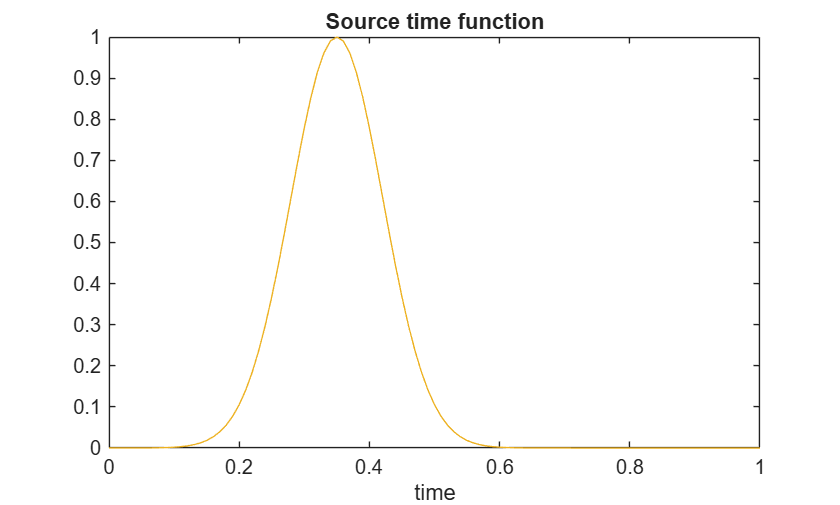

location0 = [0.33,0.43];
location1 = [0.33,0.43];
location2 = [0.33,0.43];
sourceLocation = [location0; location1; location2];
tc0 = 0.35;
tc1 = 0.35;
tc2 = 0.35;
s0 = [0,0];
s1 = [1,0];
s2 = [0,1];
w0 = @(t) exp(-((t-tc0)/0.1).^2);
w1 = @(t) exp(-((t-tc1)/0.1).^2);
w2 = @(t) exp(-((t-tc2)/0.1).^2);

monopole = MultipoleComponent2D(location0,s0,TargetField="pressure");
dipole_x = MultipoleComponent2D(location1,s1,TargetField="pressure");
dipole_y = MultipoleComponent2D(location2,s2,TargetField="pressure");
sourceComponents = {monopole,dipole_x,dipole_y};

% We spit the source into 3 terms
term0 = MultipoleSrcTerm2D(monopole,w0);
term1 = MultipoleSrcTerm2D(dipole_x,w1);
term2 = MultipoleSrcTerm2D(dipole_y,w2);
mps = MultipoleSrcSeries2D({term0,term1,term2});
spatialOrder = 4;  
source = mps.discretize(gridSp_P,gridSp_Vx,gridSp_Vy,spatialOrder);

W_data = [w0(t_rcv(:)), w1(t_rcv(:)), w2(t_rcv(:))];

figure
plot(t_rcv,W_data)
xlabel("time")
title("Source time function");

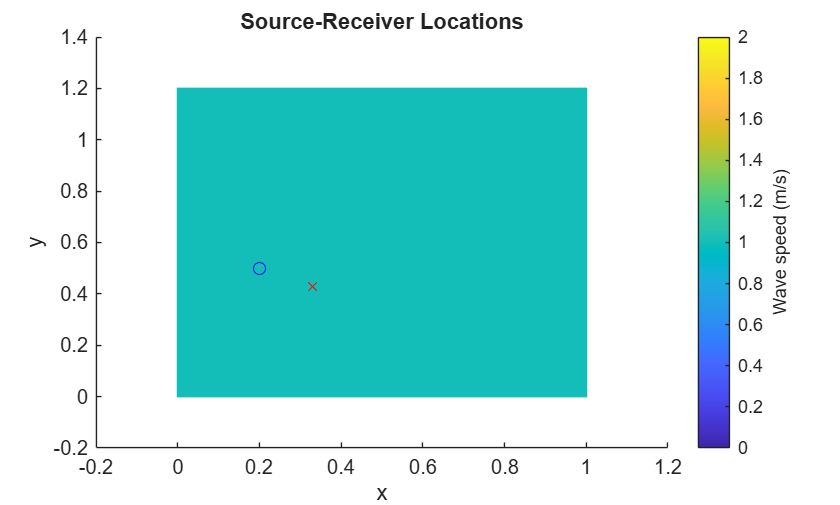

figure
plotAcqGeo(wspeed,sourceLocation,[x_rcv,y_rcv]);
title("Source-Receiver Locations")

Initializing and running solver to compute acoustic data directly.

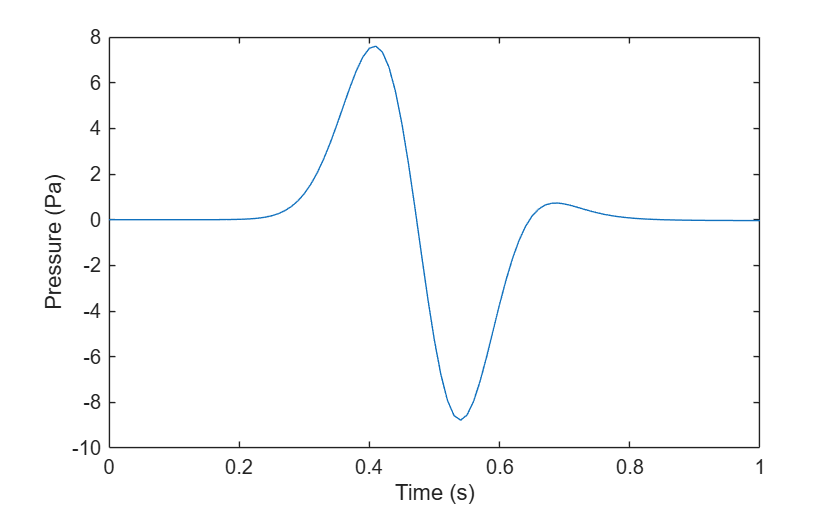

solver = AcousticSolver2D_PML( ...
    gridSp_P,   t_cmp, ...
    gridSp_rcv, t_rcv, ...
    medium, pml, ...
    SpatialOrder=spatialOrder);

[P,~,~] = solver.solve(p0,vx0,vy0,Source=source);
data = P.values(:);

P.plotTimeSeries();

## Computing pressure data via convolution

For this test the spatial and time grids are the same as those used to compute the pressure data directly. In practice, more refined grids may be used for the Green's function computation.

% Spatial computational grids and grid spaces
NxG=Nx;
NyG=Ny;

grid_x_primalG = Grid1DUnifPrimal(domain_x,NxG);
grid_y_primalG = Grid1DUnifPrimal(domain_y,NyG);
grid_x_dualG   = Grid1DUnifDual(grid_x_primalG);
grid_y_dualG   = Grid1DUnifDual(grid_y_primalG);

gridSp_PG = GridSpace2D(grid_x_primalG, grid_y_primalG);    %grid space for pressure
gridSp_VxG = GridSpace2D(grid_x_dualG,  grid_y_primalG);    %grid spaces for velocity in x
gridSp_VyG = GridSpace2D(grid_x_primalG,  grid_y_dualG);    %grid spaces for velocity in y
hG = gridSp_PG.h;    %spatial grid sizes, h = [dx,dy]

% Sampling medium parameters to compute max wave speed 
[~,~,~,~,cMaxG] = sampleMedium2D(gridSp_PG,medium);

% Determining computational time grid size
CFL_factor = 0.8;
dt_cmpG = CFL_factor*(6/7)/(cMaxG*sqrt(sum(1./hG.^2))); %CFL condition for 2-4 FDM
Nt_cmpG = ceil(diff(domain_t)/dt_cmpG)+1;
dt_cmpG = diff(domain_t)/(Nt_cmpG-1); %recomputing to ensure time domain divisible by dt

In order to carry out convolutions with the Green's function $G^p$, we will need to extend the Green's function to be defined over $[-T,T]$.

Naive approach

Given that the Green's function is casual, that is, $G^p(x,y,t)=0$ for $t<0$, we could simply compute the Green's function over the same computational time grid as the pressure data, and simply pad by zeros the result time series. There is however an issue with this approach. When discretizing the time Dirac delta function $\delta(t)$, we end up with an acoustic source that is technically not causal. Let $\tilde \delta(t)$ represent said discretization. It turns out that $\tilde \delta(t) =0$ for $t<-\Delta_t$, where $\Delta_t$ is the computational time grid size.

Smarter approach

Since we know $\tilde \delta(t)=0$ for $t<-\Delta_t$, it suffices to set the computational domain to $[-\Delta_t, T]$, and pad the computed Green's function by zeros for the remaining time interval $[-T,-\Delta t)$.

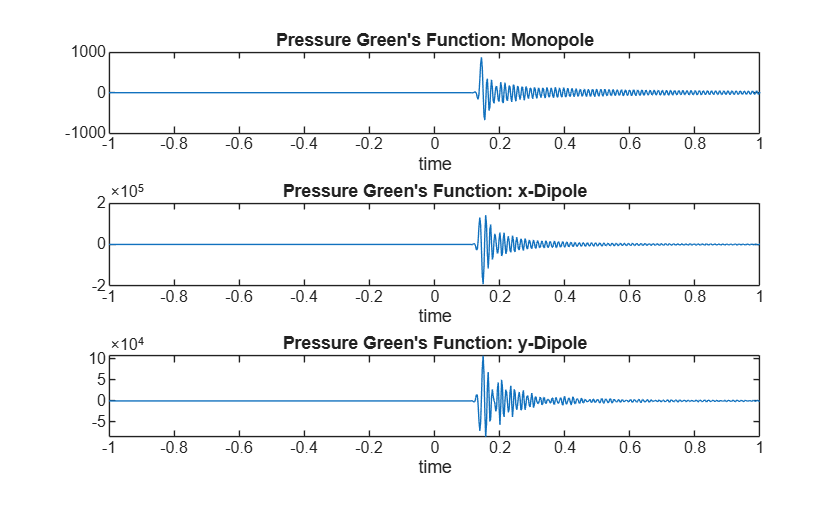

% Computational time points
t_cmpG = 0:dt_cmpG:t_final;
% Green solver times: one step before zero through t_final
t_cmpG_ext = (-1:Nt_cmpG-1)*dt_cmpG;

% Initialize solver for direct data.
solver_green = AcousticSolver2D_PML( ...
    gridSp_PG,  t_cmpG_ext, ...
    gridSp_rcv, t_cmpG_ext, ...
    medium, pml, ...
    SpatialOrder=spatialOrder);

G = AcousticGreenFunctionSeries2D( ...
    sourceComponents,solver_green,OutputField="pressure");

% Compute the impulse (Instead of the delta_t line we had previously)
G.compute(spatialOrder);

data_green = G.values;
t_ext = G.lags;

figure
subplot(3,1,1)
plot(t_ext,data_green(:,1,1))
xlabel("time")
title("Pressure Green's Function: Monopole")
subplot(3,1,2)
plot(t_ext,data_green(:,1,2))
xlabel("time")
title("Pressure Green's Function: x-Dipole")
subplot(3,1,3)
plot(t_ext,data_green(:,1,3))
xlabel("time")
title("Pressure Green's Function: y-Dipole")

Here we implement the discretization of


$$p(x_r,y_r,t) = G^p(x_r,y_r,t)* w(t)$$


by constructing the convolution matrix associated with our Green's function.

It should be noted that this discrete convolution is done the fine computational grid instead of the coarse receiver time grid. Interpolating into the coarser grid is then done after the discrete convolution to minimize interpolation errors.

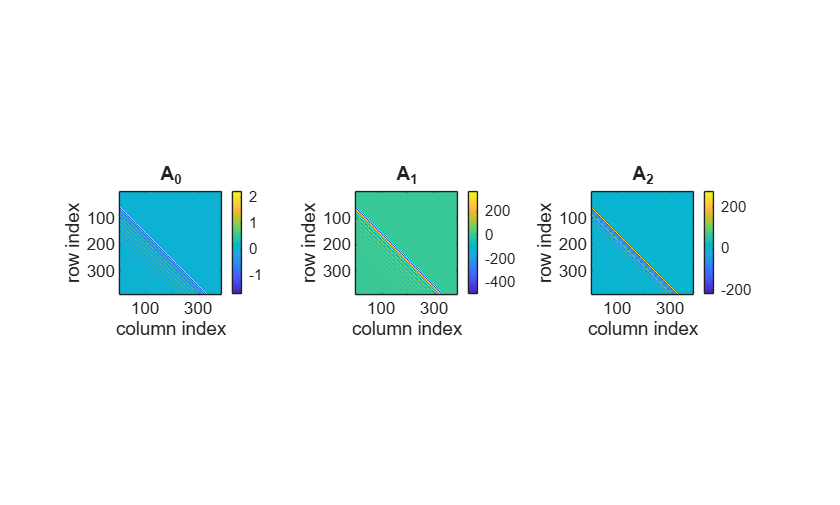

% Constructing convolution matrix (We do this differently now that we have
% functions that can manipulate linear operators)
A_op = G.makeLinearOp();
A = A_op.matrixRep();

% Here we interpolate pressure from t_cmp to t_rcv using TimeInterpOp
T_op = TimeInterpOp(t_cmpG,t_rcv,NumChannels=1);

% Now we combine the convolution and the time interpolation
A_rcv = T_op.matrixRep()*A;
A_rcv_op = MatrixLinearOp(A_rcv); 

figure
K = size(A,2)/3;
for m = 1:3
    columns = (m-1)*K+(1:K);
    A_component = A(:,columns);

    subplot(1,3,m)
    imagesc(A_component)
    axis image
    colorbar
    xlabel('column index')
    ylabel('row index')
    title(sprintf('A_%d',m-1))
end

% Computing pressure data via convolution
W_data_cmp = [w0(t_cmpG(:)), w1(t_cmpG(:)), w2(t_cmpG(:))];
w_data = W_data_cmp(:);
data_alt_cmp = A_op.fwd(w_data);

% Interpolating onto coarser receiver time grid
data_alt = T_op.fwd(data_alt_cmp);
% data_alt = interp1(t_cmpG,data_alt_cmp,t_rcv,'linear').';

Here we add in the CGLS solver. This is used to recover the source data.

% Build a zero source estimate of the true solution
w_initial = zeros(size(A_rcv,2),1);

% Run the CGLS Solver
[w_cgls,info_cgls] = solver_CGLS(...
    A_rcv_op,data_alt,...
    InitialGuess=w_initial,...
    MaxIterations=1000, ...
    TrueSolution=w_data);

% Computing pressure from the newly recovered source on the receiver time grid
data_recovered_rcv = A_rcv_op.fwd(w_cgls);

% Computing pressure from the newly recovered source on the computational time grid
data_recovered_cmp = A_op.fwd(w_cgls);

% Computing error of calculated source
source_error = norm(w_cgls-w_data)/norm(w_data);
fprintf('Relative source error: %.3e\n',source_error);

Relative source error: 1.000e+00


% Computing error of calculated pressure data (receiver time grid)
data_error = norm(data_recovered_rcv-data_alt)/norm(data_alt);
fprintf('Relative pressure error: %.3e\n',data_error);

Relative pressure error: 2.477e-06


% Checking the number of iterations:
fprintf('CGLS iterations: %d\n',info_cgls.iterations);

CGLS iterations: 45


disp(info_cgls.message)

Normal residual satisfies the relative/absolute tolerance.


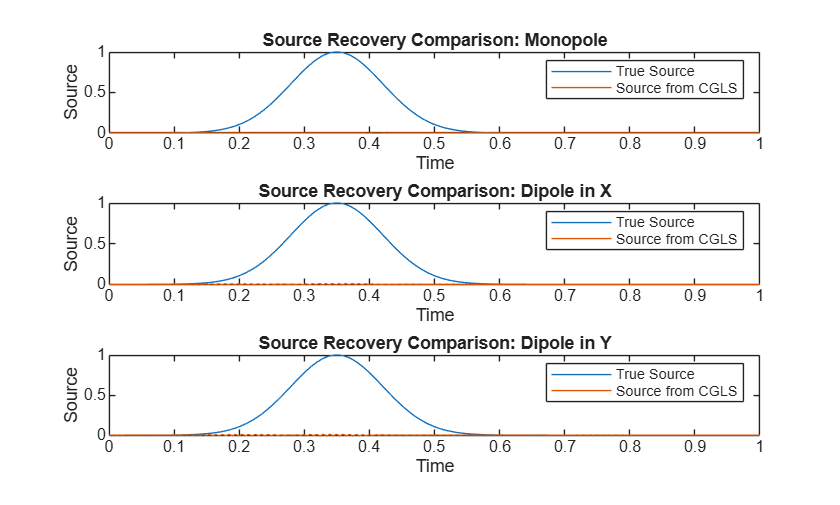

% Now let's plot some graphs to better show these results
% Comparing the calculated source against the true source
W_cgls = reshape(w_cgls,size(W_data_cmp));
graph_names = {'Monopole','Dipole in X','Dipole in Y'};

figure
for m = 1:3
    subplot(3,1,m)
    plot(t_cmpG,W_data_cmp(:,m));
    hold on
    plot(t_cmpG,W_cgls(:,m));
    hold off

    legend('True Source','Source from CGLS')
    xlabel('Time')
    ylabel('Source')
    title(['Source Recovery Comparison: ',graph_names{m}])
end

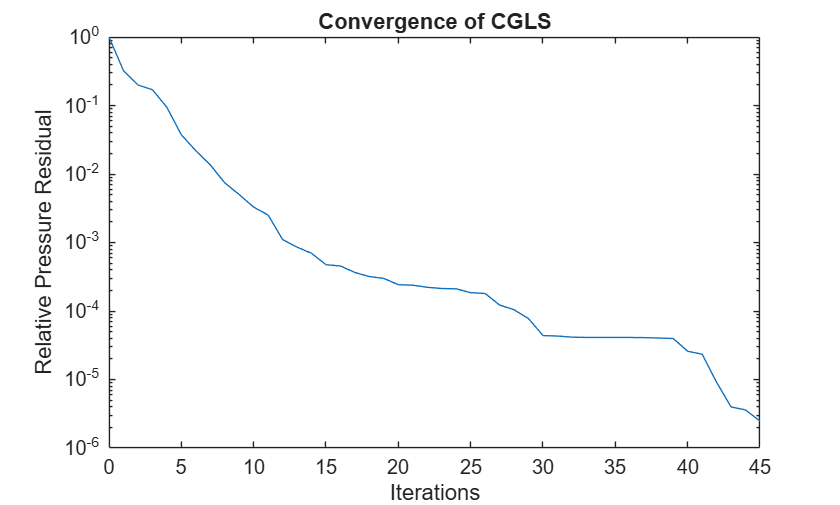

% Convergence Speed
iterations_cgls = 0:info_cgls.iterations;
relative_residual = info_cgls.dataResidualHistory/norm(data_alt);
abs_normalResidual = info_cgls.normalResidualHistory;
trueErrorHistory = info_cgls.trueErrorHistory;


figure
semilogy(iterations_cgls,relative_residual)
xlabel('Iterations')
ylabel('Relative Pressure Residual')
title('Convergence of CGLS')

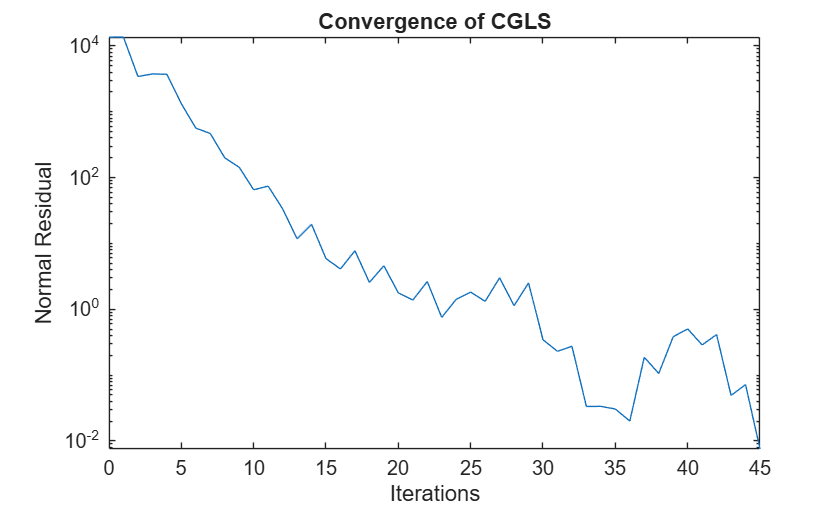

figure
semilogy(iterations_cgls,abs_normalResidual)
xlabel('Iterations')
ylabel('Normal Residual')
title('Convergence of CGLS')

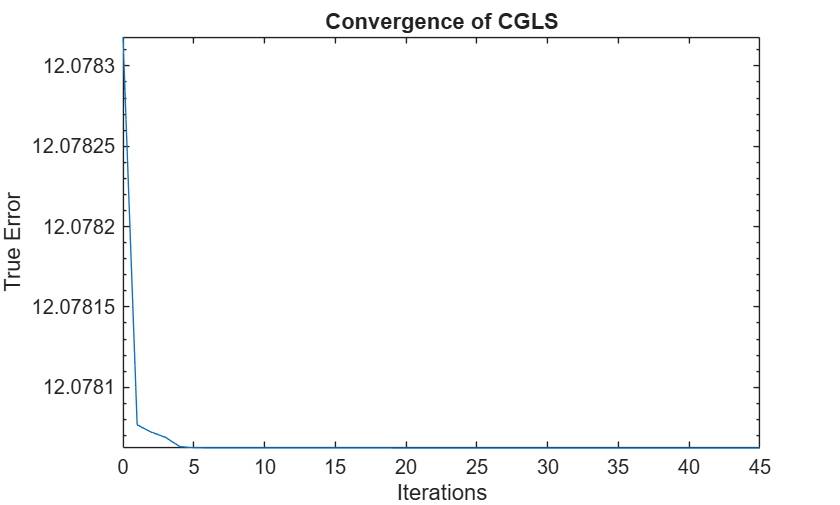

figure
semilogy(iterations_cgls,trueErrorHistory)
xlabel('Iterations')
ylabel('True Error')
title('Convergence of CGLS')

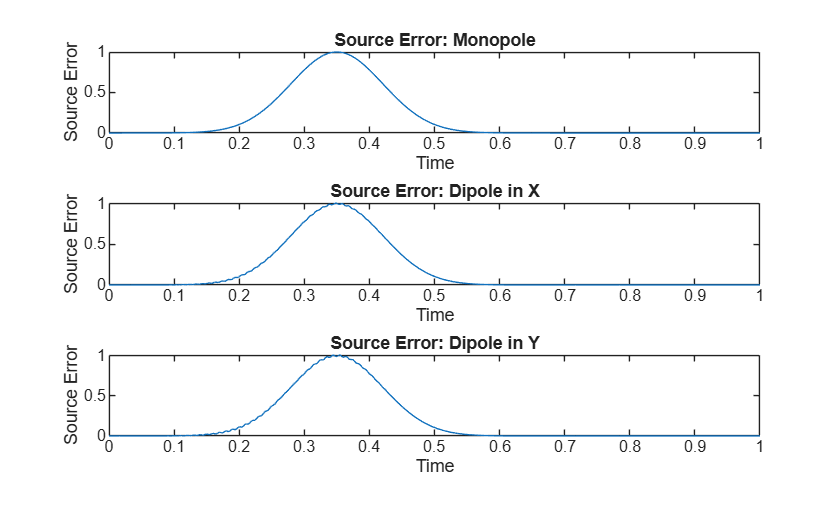

figure
for m = 1:3
    subplot(3,1,m)
    plot(t_cmpG,W_data_cmp(:,m) - W_cgls(:,m));

    xlabel('Time')
    ylabel('Source Error')
    title(['Source Error: ',graph_names{m}])
end

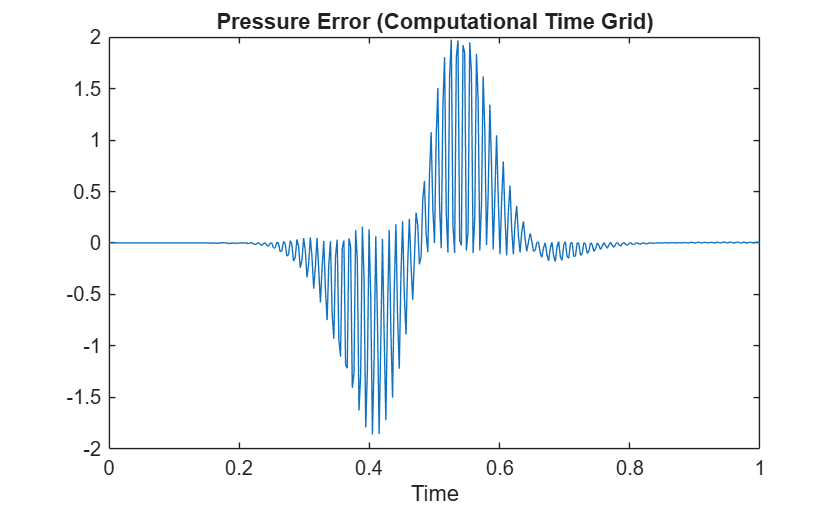

% Plotting Pressure Data Error (Computational Time Grid)
figure
plot(t_cmpG,(data_recovered_cmp-data_alt_cmp)/max(abs(data_alt_cmp)))
xlabel('Time')
title('Pressure Error (Computational Time Grid)')

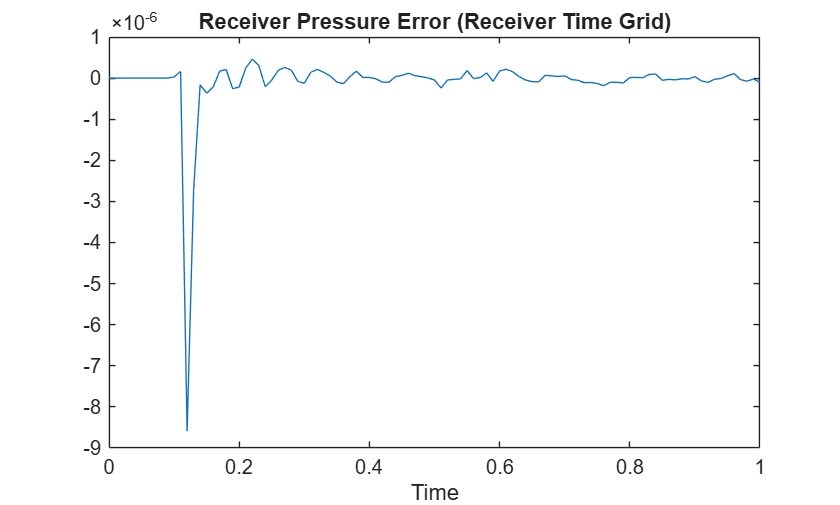

% Plotting Pressure Data Error (Receiver Time Grid)
figure
plot(t_rcv,(data_recovered_rcv-data_alt)/max(abs(data_alt)))
xlabel('Time')
title('Receiver Pressure Error (Receiver Time Grid)')